**Subplots**

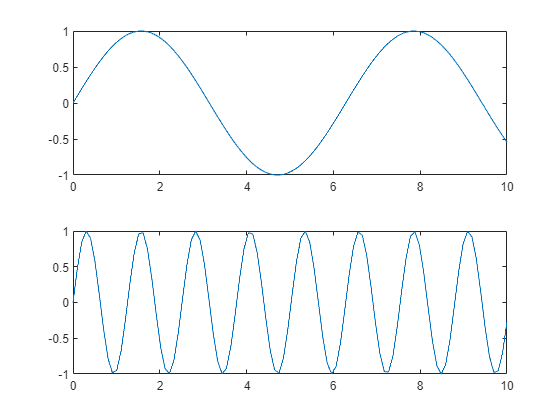

clear
subplot(2,1,1);
x = linspace(0,10);
y1 = sin(x);
plot(x,y1)

subplot(2,1,2); 
y2 = sin(5*x);
plot(x,y2)

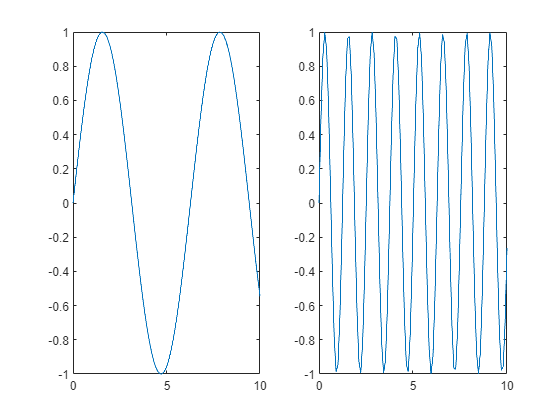

figure
subplot(1,2,1);
x = linspace(0,10);
y1 = sin(x);
plot(x,y1)

subplot(1,2,2); 
y2 = sin(5*x);
plot(x,y2)

**Ange gränser för plots**

Ex:

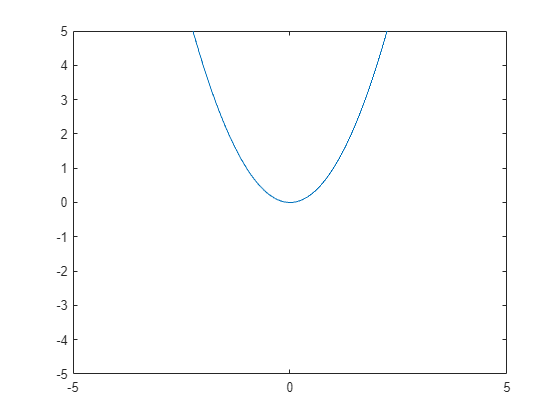

clear
func = @(x) x.^2;
t = -10:0.1:10;
plot(t,func(t)), xlim([-5 5]), ylim([-5 5])

**Räkna symboliskt**

syms x y
s1 = 2*x;
s2 = x+y;
s1 + s2

$$ans = 3\,x+y$$

**Räkna symboliska ekvationer**

clear

syms x y z
f = x+y+z;
solve(f,z)

$$ans = -x-y$$

**Simplify & expand symboliska ekvationer**

syms x
eq = (1+0.1*x)^3

$$eq = {\left(\frac{x}{10}+1\right)}^{3}$$

eq = expand(eq)

$$eq = \frac{x^{3}}{1000}+\frac{3\,x^{2}}{100}+\frac{3\,x}{10}+1$$

simplify(eq)

$$ans = \frac{{\left(x+10\right)}^{3}}{1000}$$

**Räkna symboliska ekvationssystem**

clc, clear

syms x y z
f = [2*x+z == 1, x+y+z == 0];
solve(f, [x,z])

ans = struct with fields:
    x: y + 1
    z: - 2*y - 1


Ibland ges lösningen i fields. För att nå värdena:

syms B g S I
eq = [-B*I*S+g*I == 0, B*I*S-g*I == 0, S+I == 1];
solution = solve(eq, [S I]);
S = solution.S

$$S = \left(\begin{array}{c} 1\\ \frac{g}{B} \end{array}\right)$$

I = solution.I

$$I = \left(\begin{array}{c} 0\\ \frac{B-g}{B} \end{array}\right)$$

**Lösa ekvationer**

clc, clear

f = @(x) 2*x-5;
fsolve(f,0.1)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 2.5000

Tänk på att andra parametern i fsolve är att den letar efter en lösning närmast den punkten. Tänk också på att f ska vara i formen F(x) = 0

**Lösa ekvations system**

clc, clear

syms u v
eqns = [2*u + v == 0, u - v == 1];
S = solve(eqns,[u v])

S = struct with fields:
    u: 1/3
    v: -2/3


**Räkna differentialekvationer**

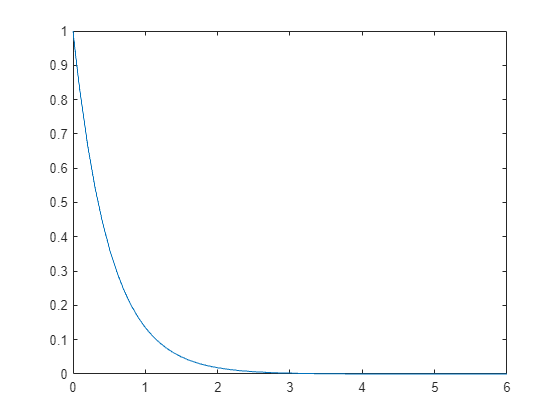

clear

x_0 = 1;
timespan = [0 6];
f = @(t,x) -2*x;
[T,Y] = ode45(f,timespan,x_0);
plot(T,Y)

Dvs att f är din diff.ekvation

**Räkna diff.ekvations system**

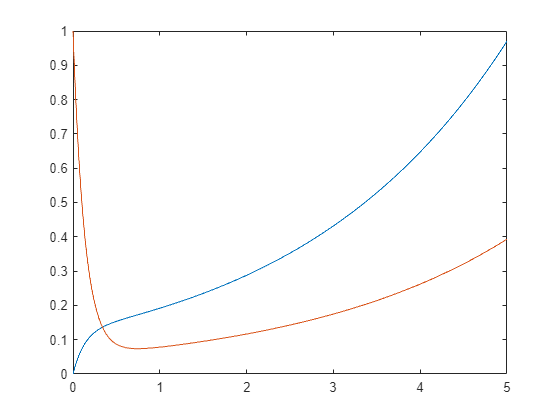

clc,clear

f = @(t,x) [x(2); 3*x(1)-7*x(2)];
x0 = [0 1];
timespan = [0 5];
[T,Y] = ode45(f,timespan,x0);
plot(T,Y)

**Simulera state-systems**

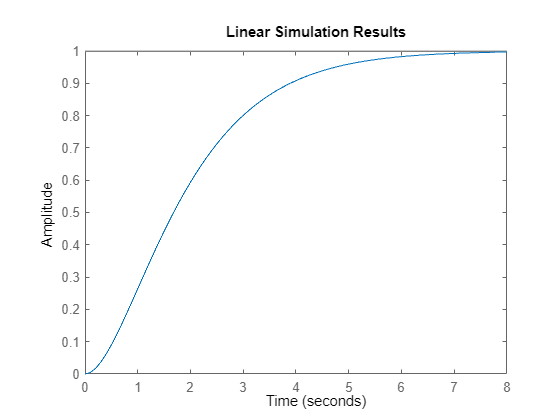

k = 1;
A = [-k 0;
    k -k];
B = [1;
    0];
C = [0 1];
D = 0;

model = ss(A, B, C, D);
t = 0:0.1:8;
u = ones(length(t), 1);
lsim(model,u,t)

Där A, B, C, D är hämtade från:

dxdt = Ax+Bu

y = Cx+Du

OBS att u vektorn måste vara lika lång som tidsvektorn

Annat värde förutom ones, använd repmat:

% u = repmat(dittvärde, rows,kolumner);

**Skapa transfer function i MATLAB från hittad transfer function**

Hitta först din transfer function

% func = tf(NUM,DEN)

numerator = 1;
denominator = [2, 3, 4]; %ange koefficienter för polynomer
func = tf(numerator, denominator)

func =
 
         1
  ---------------
  2 s^2 + 3 s + 4
 
Continuous-time transfer function.



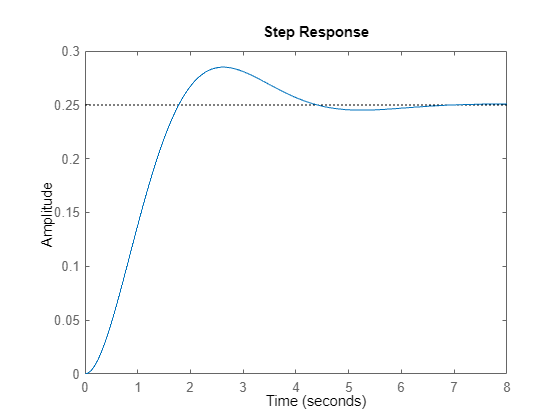

% Plotta
stepplot(func)

**State-space to transfer function**

Ex:

clear

A = [-2 -1;1 -2];
B = [1 1;2 -1];
C = [1 0];
D = [0 1];
model = ss(A,B,C,D);

func = tf(model)

func =
 
  From input 1 to output:
        s
  -------------
  s^2 + 4 s + 5
 
  From input 2 to output:
  s^2 + 5 s + 8
  -------------
  s^2 + 4 s + 5
 
Continuous-time transfer function.



**Transfer function to state-space model**

Ex:

clear

numerator = 0.16;
denominator = [1/1000 3/100 3/10 1];
tf(numerator,denominator)

ans =
 
                0.16
  --------------------------------
  0.001 s^3 + 0.03 s^2 + 0.3 s + 1
 
Continuous-time transfer function.



[A,B,C,D] = tf2ss(numerator,denominator)

A =          -30        -300       -1000
           1           0           0
           0           1           0


B =      1
     0
     0


C =      0     0   160


D = 0

**Skriva in en transfer function direkt**

s = tf('s');
G = 1/(s^2+4*s+3)

G =
 
        1
  -------------
  s^2 + 4 s + 3
 
Continuous-time transfer function.



**For-loopar**

%Skapa intervall
sum = 0;
for t = 0:1:10
    sum = sum + 1;
end
sum

sum = 11